clearvars -except hkg k l24kg xxkg
% 
in = xxkg(k);
channel = 1;
ReFs = 10;
light = 3;
p = 0.9;
lighttimes = k_lighttimes(in, light);
x1 = 0;
x2 = 300;

%% Prepare raw data variables

    %outlier removal
     tto = [in.idx(channel).obwidx]; 
          
    %raw data
        timcont = [in.e(channel).s(tto).timcont]; %time in seconds
        obw = [in.e(channel).s(tto).obwAmp]/max([in.e(channel).s(tto).obwAmp]); %divide by max to normalize
        oldfreq = timcont;
  %Make a time base that starts and ends on lighttimes 
    %raw data
            rawidx = timcont >= lighttimes(1) & timcont <= lighttimes(end);
            timmy = timcont(rawidx);
            obwAmp = obw(rawidx);       

%subspline subtraction
splinexx = lighttimes(1):ReFs:lighttimes(end); %resample x

        %spline of raw data
        spliney1 = csaps(timcont, obw, p);
        %estimate without resample
        obwall = fnval(timcont, spliney1);
        %estimate with resample
        obwyyOG = fnval(splinexx, spliney1);

        %take raw data above the spline
        topidx = find(obw > obwall);
        topobw = obw(topidx);
        toptim = timcont(topidx);
        
       
        %spline of above spline data
        spliney2 = csaps(toptim, topobw, p);
        %resample based on regularized time data
        topobwyy = fnval(splinexx, spliney2);


        %take raw data below the spine
        %take raw data above the spline
        botidx = find(obw < obwall);
        botobw = obw(botidx);
        bottim = timcont(botidx);

        %spline of above spline data
        spliney3 = csaps(bottim, botobw, p);
        %resample based on regularized time data
        botobwyy = fnval(splinexx, spliney3);


        midobwyy = mean([topobwyy; botobwyy]);

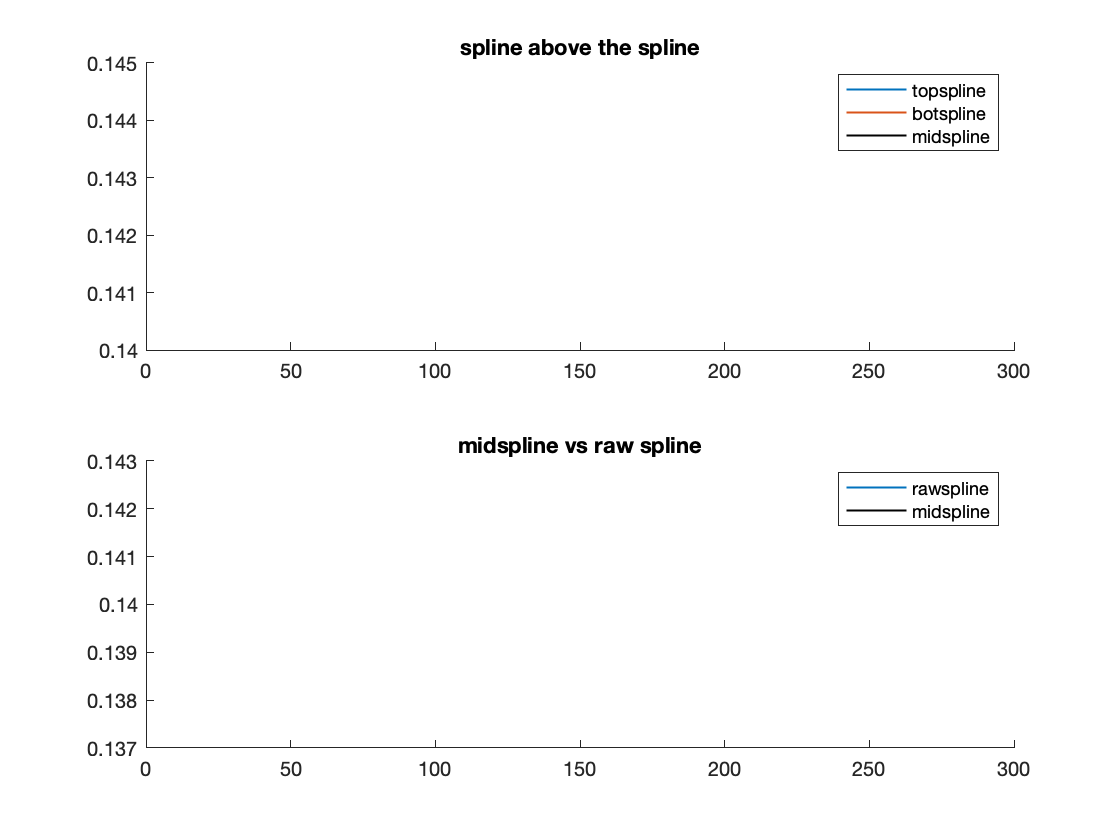


%% plot to see
figure(60); clf; title('splines'); hold on;%ylim = ([0,.8]);
    ax(1) = subplot(211); title('spline above the spline'); xlim([x1, x2]);hold on;
     
        %fill boxes
            a = ylim; %all of above is just to get the max for the plot lines...
            if light < 4 %the first lighttime is dark
                for j = 1:length(lighttimes)-1
                    if mod(j,2) == 1 %if j is odd
                    fill([lighttimes(j)/3600 lighttimes(j)/3600 lighttimes(j+1)/3600 lighttimes(j+1)/3600], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9], 'HandleVisibility','off');
                    end
                end
            else %the second lighttime is dark 
                for j = 1:length(lighttimes)-1
                    if mod(j,2) == 0 %if j is even
                    fill([lighttimes(j)/3600 lighttimes(j)/3600 lighttimes(j+1)/3600 lighttimes(j+1)/3600], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9], 'HandleVisibility','off');
                    end
                end
            end

      
        plot(splinexx/3600, topobwyy, 'DisplayName', 'topspline', 'LineWidth', 1);
        plot(splinexx/3600, botobwyy, 'DisplayName', 'botspline','LineWidth', 1);
       % plot(splinexx/3600, obwyyOG, 'DisplayName', 'rawspline','LineWidth', 1);
        plot(splinexx/3600, midobwyy, 'k', 'DisplayName', 'midspline','LineWidth', 1);
        plot(timmy/3600, obwAmp, '.', 'MarkerSize', 10);
  
legend;

     ax(2) = subplot(212); title('midspline vs raw spline'); xlim([x1, x2]);hold on;

      %fill boxes
            a = ylim; %all of above is just to get the max for the plot lines...
            if light < 4 %the first lighttime is dark
                for j = 1:length(lighttimes)-1
                    if mod(j,2) == 1 %if j is odd
                    fill([lighttimes(j)/3600 lighttimes(j)/3600 lighttimes(j+1)/3600 lighttimes(j+1)/3600], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9], 'HandleVisibility','off');
                    end
                end
            else %the second lighttime is dark 
                for j = 1:length(lighttimes)-1
                    if mod(j,2) == 0 %if j is even
                    fill([lighttimes(j)/3600 lighttimes(j)/3600 lighttimes(j+1)/3600 lighttimes(j+1)/3600], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9], 'HandleVisibility','off');
                    end
                end
            end

      
       
        plot(splinexx/3600, obwyyOG, 'DisplayName', 'rawspline','LineWidth', 1);
        plot(splinexx/3600, midobwyy, 'k', 'DisplayName', 'midspline','LineWidth', 1);
        plot(timmy/3600, obwAmp, '.', 'MarkerSize', 10);
  
legend;

linkaxes(ax, 'x');

%peaks of peaks
        %find peaks
        [obwpeak1,LOCS] = findpeaks(obw);
        peaktim1 = timcont(LOCS);
        %find peaks of the peaks
        [obwpeak2,cLOCS] = findpeaks(obw(LOCS));
        peaktim2 = timcont(LOCS(cLOCS));

peakidx1 = find(peaktim1 >= lighttimes(1) & peaktim1 <= lighttimes(end));
peaktim1 = peaktim1(peakidx1);
obwpeak1 = obwpeak1(peakidx1);

peakidx2 = find(peaktim2 >= lighttimes(1) & peaktim2 <= lighttimes(end));
peaktim2 = peaktim2(peakidx2);
obwpeak2 = obwpeak2(peakidx2);

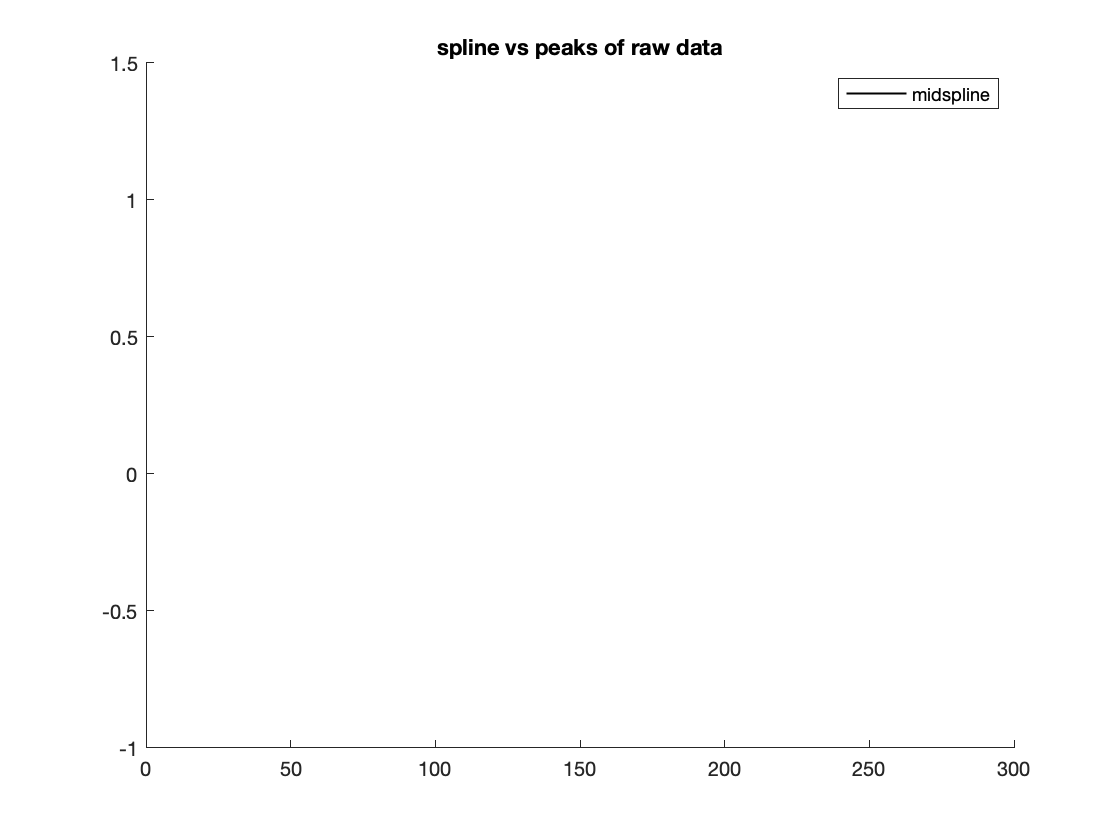

figure(62); clf; title('spline vs peaks of raw data'); ylim = ([0,.8]); xlim([x1, x2]);hold on;
  
       
        %fill boxes
            a = ylim; %all of above is just to get the max for the plot lines...
            if light < 4 %the first lighttime is dark
                for j = 1:length(lighttimes)-1
                    if mod(j,2) == 1 %if j is odd
                    fill([lighttimes(j)/3600 lighttimes(j)/3600 lighttimes(j+1)/3600 lighttimes(j+1)/3600], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9], 'HandleVisibility','off');
                    end
                end
            else %the second lighttime is dark 
                for j = 1:length(lighttimes)-1
                    if mod(j,2) == 0 %if j is even
                    fill([lighttimes(j)/3600 lighttimes(j)/3600 lighttimes(j+1)/3600 lighttimes(j+1)/3600], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9], 'HandleVisibility','off');
                    end
                end
            end

      
       
        plot(peaktim1/3600, obwpeak1, 'DisplayName', 'obw peaks','LineWidth', 1);
         plot(peaktim2/3600, obwpeak2, 'DisplayName', 'peaks of obw peaks','LineWidth', 1);
        plot(splinexx/3600, midobwyy, 'k', 'DisplayName', 'midspline','LineWidth', 1);
        plot(timmy/3600, obwAmp, '.', 'MarkerSize', 10);
  
legend;

 %find peaks
        [splinepeak1,LOCS] = findpeaks(midobwyy);

Error using findpeaks>parse_inputs
Data set must contain at least 3 samples.

Error in findpeaks (line 135)
  = parse_inputs(isInMATLAB,Yin,varargin{:});

        splinetim1 = splinexx(LOCS);
        %find peaks of the peaks
        [splinepeak2,cLOCS] = findpeaks(midobwyy(LOCS));
        splinetim2 = splinexx(LOCS(cLOCS));

%resample test
 %spline of above spline data
        spliney4 = csaps(splinetim1, splinepeak1, p);
        %resample based on regularized time data
        spinepeak1yy = fnval(splinexx, spliney4);

 %spline of raw peaks of peaks
        spliney5 = csaps(splinetim2, splinepeak2, p);
        %resample based on regularized time data
        spinepeak2yy = fnval(splinexx, spliney5); 


figure(63); clf; title('peaks of spline'); ylim = ([0,.8]); xlim([x1, x2]);hold on;
  
       ax(1) = subplot(211); title('spline peaks'); hold on; xlim([x1, x2]);
        %fill boxes
            a = ylim; %all of above is just to get the max for the plot lines...
            if light < 4 %the first lighttime is dark
                for j = 1:length(lighttimes)-1
                    if mod(j,2) == 1 %if j is odd
                    fill([lighttimes(j)/3600 lighttimes(j)/3600 lighttimes(j+1)/3600 lighttimes(j+1)/3600], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9], 'HandleVisibility','off');
                    end
                end
            else %the second lighttime is dark 
                for j = 1:length(lighttimes)-1
                    if mod(j,2) == 0 %if j is even
                    fill([lighttimes(j)/3600 lighttimes(j)/3600 lighttimes(j+1)/3600 lighttimes(j+1)/3600], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9], 'HandleVisibility','off');
                    end
                end
            end

      
       
        plot(splinetim1/3600, splinepeak1, 'DisplayName', 'spline peaks','LineWidth', 1);
         plot(splinetim2/3600, splinepeak2, 'DisplayName', 'peaks of spline peaks','LineWidth', 1);
        plot(splinexx/3600, midobwyy, 'k', 'DisplayName', 'midspline','LineWidth', 1);
        plot(timmy/3600, obwAmp, '.', 'MarkerSize', 10);
  
        legend;


    ax(2) = subplot(212); title('spline of spline peaks'); hold on; xlim([x1, x2]);
        %fill boxes
            a = ylim; %all of above is just to get the max for the plot lines...
            if light < 4 %the first lighttime is dark
                for j = 1:length(lighttimes)-1
                    if mod(j,2) == 1 %if j is odd
                    fill([lighttimes(j)/3600 lighttimes(j)/3600 lighttimes(j+1)/3600 lighttimes(j+1)/3600], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9], 'HandleVisibility','off');
                    end
                end
            else %the second lighttime is dark 
                for j = 1:length(lighttimes)-1
                    if mod(j,2) == 0 %if j is even
                    fill([lighttimes(j)/3600 lighttimes(j)/3600 lighttimes(j+1)/3600 lighttimes(j+1)/3600], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9], 'HandleVisibility','off');
                    end
                end
            end

      
       
         plot(splinexx/3600, spinepeak1yy, 'DisplayName', 'spline of spline peaks','LineWidth', 1);
          plot(splinexx/3600, spinepeak2yy, 'DisplayName', 'spline of spline peaks of peaks','LineWidth', 1);
        plot(splinexx/3600, midobwyy, 'k', 'DisplayName', 'midspline','LineWidth', 1);
        plot(timmy/3600, obwAmp, '.', 'MarkerSize', 10);
  
        legend;
  linkaxes(ax, 'x');

%resample test
 %spline of above spline data
        spliney4 = csaps(splinetim1, splinepeak1, p);
        %resample based on regularized time data
        spinepeak1yy = fnval(splinexx, spliney4);

 %spline of raw peaks of peaks
        spliney4 = csaps(splinetim1, splinepeak1, p);
        %resample based on regularized time data
        spinepeak1yy = fnval(splinexx, spliney4); 


figure(63); clf; title('peaks of spline'); ylim = ([0,.8]); xlim([x1, x2]);hold on;
  
     %  ax(1) = subplot(211); title('spline peaks vs raw peaks')
        %fill boxes
            a = ylim; %all of above is just to get the max for the plot lines...
            if light < 4 %the first lighttime is dark
                for j = 1:length(lighttimes)-1
                    if mod(j,2) == 1 %if j is odd
                    fill([lighttimes(j)/3600 lighttimes(j)/3600 lighttimes(j+1)/3600 lighttimes(j+1)/3600], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9], 'HandleVisibility','off');
                    end
                end
            else %the second lighttime is dark 
                for j = 1:length(lighttimes)-1
                    if mod(j,2) == 0 %if j is even
                    fill([lighttimes(j)/3600 lighttimes(j)/3600 lighttimes(j+1)/3600 lighttimes(j+1)/3600], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9], 'HandleVisibility','off');
                    end
                end
            end

      
       
        plot(splinetim1/3600, splinepeak1, 'DisplayName', 'spline peaks','LineWidth', 1);
         plot(splinexx/3600, spinepeak1yy, 'DisplayName', 'spline of spline peaks','LineWidth', 1.5);
          plot(peaktim2/3600, obwpeak2, 'DisplayName', 'peaks of obw peaks','LineWidth', 1);
      %  plot(splinexx/3600, midobwyy, 'k', 'DisplayName', 'midspline','LineWidth', 1);
        plot(timmy/3600, obwAmp, '.', 'MarkerSize', 10);
  
legend;

  

%peaks of peaks - splines
        %find peaks
        [obwpeak1,LOCS] = findpeaks(obw);
        peaktim1 = timcont(LOCS);
        %find peaks of the peaks
        [obwpeak2,cLOCS] = findpeaks(obw(LOCS));
        peaktim2 = timcont(LOCS(cLOCS));

peakidx1 = find(peaktim1 >= lighttimes(1) & peaktim1 <= lighttimes(end));
peaktim1 = peaktim1(peakidx1);
obwpeak1 = obwpeak1(peakidx1);

peakidx2 = find(peaktim2 >= lighttimes(1) & peaktim2 <= lighttimes(end));
peaktim2 = peaktim2(peakidx2);
obwpeak2 = obwpeak2(peakidx2);


%resample test
 %spline of above spline data
        spliney6 = csaps(peaktim1, obwpeak1, p);
        %resample based on regularized time data
        obwpeak1yy = fnval(splinexx, spliney6);

 %spline of raw peaks of peaks
         spliney7 = csaps(peaktim2, obwpeak2, p);
        %resample based on regularized time data
        obwpeak2yy = fnval(splinexx, spliney7);

figure(67); clf; title('spline of peaks'); ylim = ([0,.8]);hold on;
  
       ax(1) = subplot(211); title('raw data peaks'); hold on; xlim([x1, x2]);
        %fill boxes
            a = ylim; %all of above is just to get the max for the plot lines...
            if light < 4 %the first lighttime is dark
                for j = 1:length(lighttimes)-1
                    if mod(j,2) == 1 %if j is odd
                    fill([lighttimes(j)/3600 lighttimes(j)/3600 lighttimes(j+1)/3600 lighttimes(j+1)/3600], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9], 'HandleVisibility','off');
                    end
                end
            else %the second lighttime is dark 
                for j = 1:length(lighttimes)-1
                    if mod(j,2) == 0 %if j is even
                    fill([lighttimes(j)/3600 lighttimes(j)/3600 lighttimes(j+1)/3600 lighttimes(j+1)/3600], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9], 'HandleVisibility','off');
                    end
                end
            end

      
       
         plot(peaktim1/3600, obwpeak1, 'DisplayName', 'obw peaks','LineWidth', 1);
         plot(peaktim2/3600, obwpeak2, 'DisplayName', 'peaks of obw peaks','LineWidth', 1);
        
        plot(timmy/3600, obwAmp, '.', 'MarkerSize', 10);
  
        legend;


    ax(2) = subplot(212); title('spline of raw peaks'); hold on; xlim([x1, x2]);
        %fill boxes
            a = ylim; %all of above is just to get the max for the plot lines...
            if light < 4 %the first lighttime is dark
                for j = 1:length(lighttimes)-1
                    if mod(j,2) == 1 %if j is odd
                    fill([lighttimes(j)/3600 lighttimes(j)/3600 lighttimes(j+1)/3600 lighttimes(j+1)/3600], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9], 'HandleVisibility','off');
                    end
                end
            else %the second lighttime is dark 
                for j = 1:length(lighttimes)-1
                    if mod(j,2) == 0 %if j is even
                    fill([lighttimes(j)/3600 lighttimes(j)/3600 lighttimes(j+1)/3600 lighttimes(j+1)/3600], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9], 'HandleVisibility','off');
                    end
                end
            end

      
       
         plot(splinexx/3600, obwpeak1yy, 'DisplayName', 'spline raw peaks','LineWidth', 1);
          plot(splinexx/3600, obwpeak2yy, 'DisplayName', 'spline of raw peaks of peaks','LineWidth', 1);
      
        plot(timmy/3600, obwAmp, '.', 'MarkerSize', 10);
  
        legend;
 linkaxes(ax, 'x');

figure(68); clf; title('peaks of peaks vs spline of spline peaks'); ylim = ([0,.8]); xlim([x1, x2]);hold on;
  
     %  ax(1) = subplot(211); title('spline peaks vs raw peaks')
        %fill boxes
            a = ylim; %all of above is just to get the max for the plot lines...
            if light < 4 %the first lighttime is dark
                for j = 1:length(lighttimes)-1
                    if mod(j,2) == 1 %if j is odd
                    fill([lighttimes(j)/3600 lighttimes(j)/3600 lighttimes(j+1)/3600 lighttimes(j+1)/3600], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9], 'HandleVisibility','off');
                    end
                end
            else %the second lighttime is dark 
                for j = 1:length(lighttimes)-1
                    if mod(j,2) == 0 %if j is even
                    fill([lighttimes(j)/3600 lighttimes(j)/3600 lighttimes(j+1)/3600 lighttimes(j+1)/3600], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9], 'HandleVisibility','off');
                    end
                end
            end

      
       
         plot(peaktim2/3600, obwpeak2, 'DisplayName', 'peaks of raw peaks','LineWidth', 1.5);
         % plot(splinetim1/3600, splinepeak1, 'DisplayName', 'peaks of spline','LineWidth', 1.5);
        % plot(splinexx/3600, spinepeak1yy, 'DisplayName', 'spline of spline peaks','LineWidth', 1);
     %   plot(peaktim1/3600, obwpeak1, 'DisplayName', 'obw peaks','LineWidth', 1);
            plot(splinexx/3600, obwyyOG, 'DisplayName', 'spline','LineWidth', 1);
      %  plot(splinexx/3600, midobwyy, 'k', 'DisplayName', 'midspline','LineWidth', 1);
        plot(timmy/3600, obwAmp, '.', 'MarkerSize', 10);
  
%legend;

  

figure(69); clf; title('peaks of peaks vs spline of peaks of peaks'); ylim = ([0,.8]); xlim([x1, x2]);hold on;
 %cubic vs linear interp.
     %  ax(1) = subplot(211); title('spline peaks vs raw peaks')
        %fill boxes
            a = ylim; %all of above is just to get the max for the plot lines...
            if light < 4 %the first lighttime is dark
                for j = 1:length(lighttimes)-1
                    if mod(j,2) == 1 %if j is odd
                    fill([lighttimes(j)/3600 lighttimes(j)/3600 lighttimes(j+1)/3600 lighttimes(j+1)/3600], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9], 'HandleVisibility','off');
                    end
                end
            else %the second lighttime is dark 
                for j = 1:length(lighttimes)-1
                    if mod(j,2) == 0 %if j is even
                    fill([lighttimes(j)/3600 lighttimes(j)/3600 lighttimes(j+1)/3600 lighttimes(j+1)/3600], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9], 'HandleVisibility','off');
                    end
                end
            end

      
       
         plot(peaktim2/3600, obwpeak2, 'DisplayName', 'peaks of raw peaks','LineWidth', 1);
          plot(splinexx/3600, obwpeak2yy, 'DisplayName', 'spline of raw peaks of peaks','LineWidth', 1);
         % plot(splinetim1/3600, splinepeak1, 'DisplayName', 'peaks of spline','LineWidth', 1.5);
        % plot(splinexx/3600, spinepeak1yy, 'DisplayName', 'spline of spline peaks','LineWidth', 1);
     %   plot(peaktim1/3600, obwpeak1, 'DisplayName', 'obw peaks','LineWidth', 1);
    %        plot(splinexx/3600, obwyyOG,'k', 'DisplayName', 'spline','LineWidth', 1);
      %  plot(splinexx/3600, midobwyy, 'k', 'DisplayName', 'midspline','LineWidth', 1);
        plot(timmy/3600, obwAmp, '.', 'MarkerSize', 10);
  
%legend;
